clear all
close all
clc

## Hearing Range in Animals

% the hearing range for human is around 20Hz to 20Hz
% the hearing range for a wide range of species is different
% the same sound might not sound the same according to different animals
% the goal is to look at frequency domain of sounds
% adjust the filtering band for different animals
% compare the frequency domain of processed sound to original
% compare the sounds

## Open File

% ask the user to pick one type of sound out of 3 listed
% 1.laughing 2.screaming 3.sneezing
file_choice=input(['which sound do you perfer to analyze?\n1.laughing, 2.screaming or 3.sneezing'])

file_choice = 2

% according to the choice, prepare differet file to read
if file_choice==1
    file_read='Man laughing 3.wav';
    % title_name will be used later title in figures
    title_name=' laughing';
elseif file_choice==2
    file_read='Man screaming 1.wav';
    title_name=' screaming';
elseif file_choice==3
    file_read='Man sneezing.wav'; 
    title_name=' sneezing';
end

## Read the Audio File

% read the audio file, assign two variables y and SampleRate
[y,SampleRate]=audioread(file_read);
% find max from y for later to set y scale
y_axis_audio=max(y);
% find the length of y vector 
% total time of audio is total number of sample divide by sample rate
% create a vector for time with number of points correspond to length_y
length_y=length(y);
Time_audio=length_y/SampleRate;
Timeline_vector=linspace(0,Time_audio,length_y);

## Plot the Audio Data

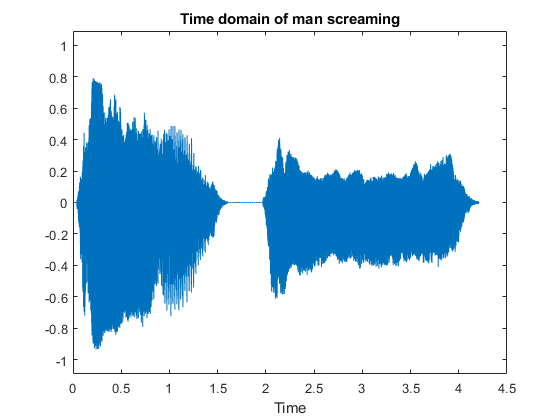

% create a new figure and plot time against y
% add lable and title
figure
plot(Timeline_vector,y);
xlabel('Time');
% set limit on y axis
ylim([-y_axis_audio-0.3 y_axis_audio+0.3]);
% combine string together to form new string for title
title_string=strcat('Time domain of man ',title_name);
title(title_string);

## Fast Fourier Transformation

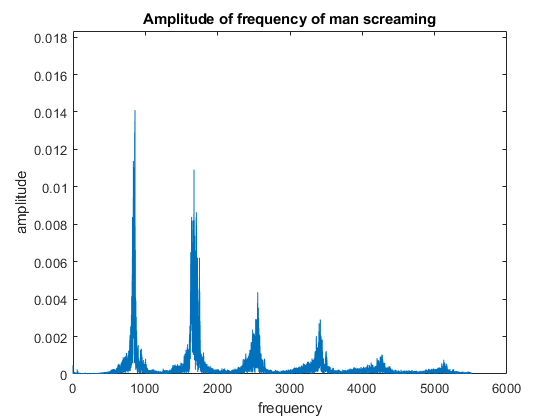

% Run a fft on y and plot the amplitude against frequency 

% Y is a vector of amplitude coefficient normalized
Y=fft(y)/length_y;
% the Nyquist limit is half of sampling frequency
Nylimit=SampleRate/2;
% create a vector for frequency domain
% max is the Nyquist limit
frequency_domain=linspace(0,1,floor(length_y/2))*Nylimit;
% get the absolute value of amplitude of frequency
% floor(length_y/2) ensures that a integer index is returned
amplitude_frequency=abs(Y(1:floor(length_y/2)));
% find max from amplitude_frequency later y axis scale
fft_y_axis=max(amplitude_frequency);

% plot amplitude against frequency domain
% label the x and y axis
figure
plot(frequency_domain,amplitude_frequency);
% set y axis limit according to max value of fft 
ylim([0 fft_y_axis*1.3]);
xlabel('frequency');
ylabel('amplitude');
title_string2=strcat('Amplitude of frequency of man ', title_name);
title(title_string2);

## Spectrogram View of audio Data

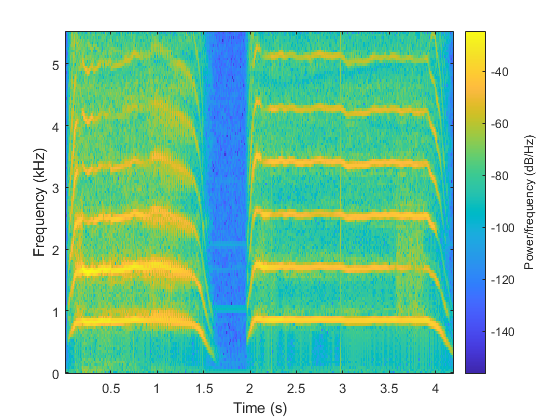

% set the window size as 2^8
% plot the spectrogram with frequency on the y axis
WinN = pow2(8);
spectrogram(y,WinN,[],[],SampleRate,'yaxis');

## Animal Hearing Range

% different animals have different hearing range
% this program includes hearing range for the following animals
% goldfish, tuna, mouse, bullfrog, chicken and bat
goldfish=1;
tuna=2;
mouse=3;
bullfrog=4;
chicken=5;
bat=6;
title_list=["goldfish", "tuna", "mouse", "bullfrog", "chicken", "bat"];
% set a vector with each row corresponding to hearing band
% note for catfish and bat the high limit is higher than Nylimit
% we set top range for these two animals to be Nylimit-1
hear_range=[20 3000; 50 1100; 1000 Nylimit-1; 100 3000; 125 2000; 2000 Nylimit-1];


## Run filter and plot new audio data

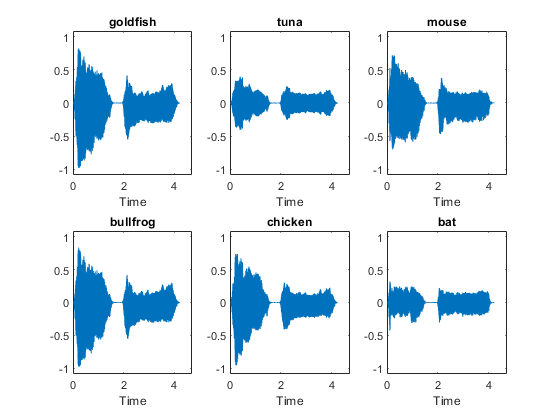

% set degree of butterworth filter
% the freqency band pass should be between 0 to 1
% we set 1 as Nylimit/Nylimit
% for individual frequency, the fpass will be frequency/Nylimit
% use a while loop to run filter and plot all new audio data
ii=1;
figure
new_y=[];
while ii<=6
    n=4; 
    fpass=hear_range(ii,:)./Nylimit;
    [b,a]=butter(n,fpass);
    % filter according to the band set, and return new set of y value
    new_y(:,ii)=filtfilt(b,a,y);
    
    % make new figure
    % plot new y against time
    % label x axis and title
    subplot(2,3,ii);
    plot(Timeline_vector,new_y(:,ii));
    % set the limit for x and y axis
    xlim([0 Time_audio+0.5]);
    % set the y axis same as before filter
    ylim([-y_axis_audio-0.3 y_axis_audio+0.3]);
    xlabel('Time');
    title(title_list(1,ii));
    hold on
    ii=ii+1;
end

## Spectrogram and fft for filtered signal

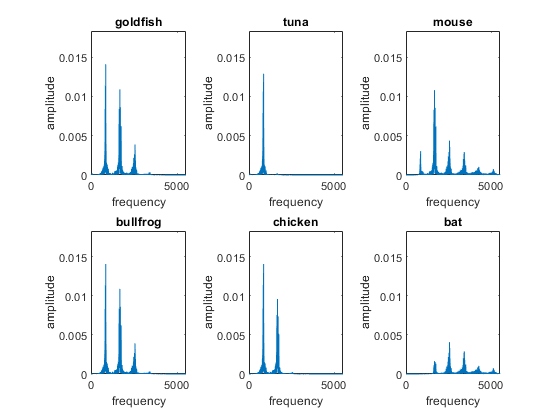

% Run a fft on new_y and plot the amplitude against frequency 
% we see differences on the audio data after filter
% the differences is hard to charaterize 
% we run fft and spectrogram to observe the differences

% new_Y is a maxtrix of amplitude coefficient normalized
new_Y=fft(new_y)/length_y;
% get the absolute value of amplitude of frequency
% floor(length_y/2) ensures that a integer index is returned
new_amplitude_frequency=abs(new_Y(1:floor(length_y/2),:));
 
% plot amplitude against frequency domain
% label the x and y axis
% use a while loop
ii=1;
figure
while ii<=6
    subplot(2,3,ii);
    plot(frequency_domain,new_amplitude_frequency(:,ii));
    % set the y axis limit to be same as before filter
    ylim([0 fft_y_axis*1.3]);
    xlabel('frequency');
    ylabel('amplitude');
    title(title_list(1,ii)); 
    hold on
    ii=ii+1;
end

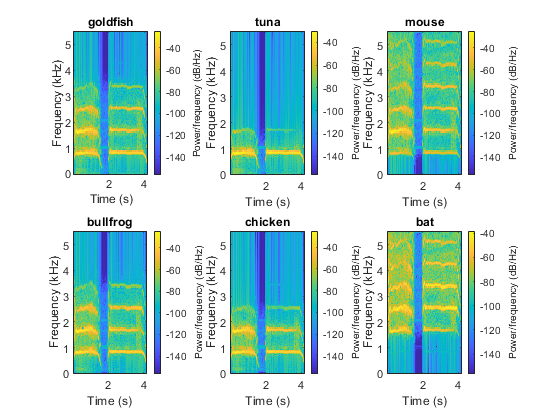


% Make spectrogram of new_y
% set the window size as 2^8
% plot the spectrogram with frequency on the y axis
% similar to before, plot 6 plots on 1 figure
jj=1;
figure
while jj<=6
    WinN = pow2(8);
    subplot(2,3,jj);
    spectrogram(new_y(:,jj),WinN,[],[],SampleRate,'yaxis');  
    title(title_list(1,jj));
    hold on
    jj=jj+1;
end

## Play the original sound

sound(y, SampleRate)

## Play the filtered sound

% prompt user to pick an animal
sound_pick=input('Which animal you want to pick to listen?\n1.goldfish 2.tuna 3.mouse 4.bullfrog 5.chicken 6.bat');
sound(new_y(:,sound_pick),SampleRate)
